## Method and Materials - Forward Kinematics

Here we will describe the approach to model, simulate, and analyze the ice-cream dispensing robot. In this section, we will discuss the derivation of forward kinematics, construct of the Jacobian for singularity analysis, derive the algorithm for numerical inverse kinematics, and discuss our approach to trajectory planning.

Forward kinematics refers to the process of calculating the position and orientation of a robot’s end-effector (or any desired final frame) with respect to a base frame. This is useful in order to keep track of the robot’s end-effector given a set of input joint angles or displacements. Here we follow the Denavit-Hartenberg (DH) convention for forward kinematic derivation. The figure below displays the robot and the assigned frames. 

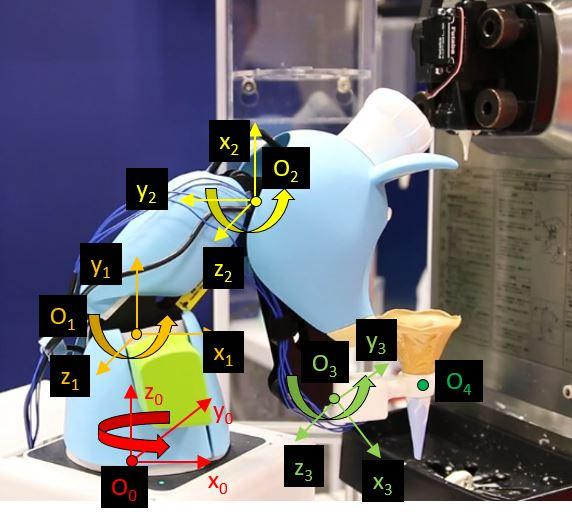

This is a RRRR style manipulator. Below we show the frames and joint angles in home configuration. Note that $O_3$ is at an angle $\gamma$ from the vertical with respect to $O_2$. 

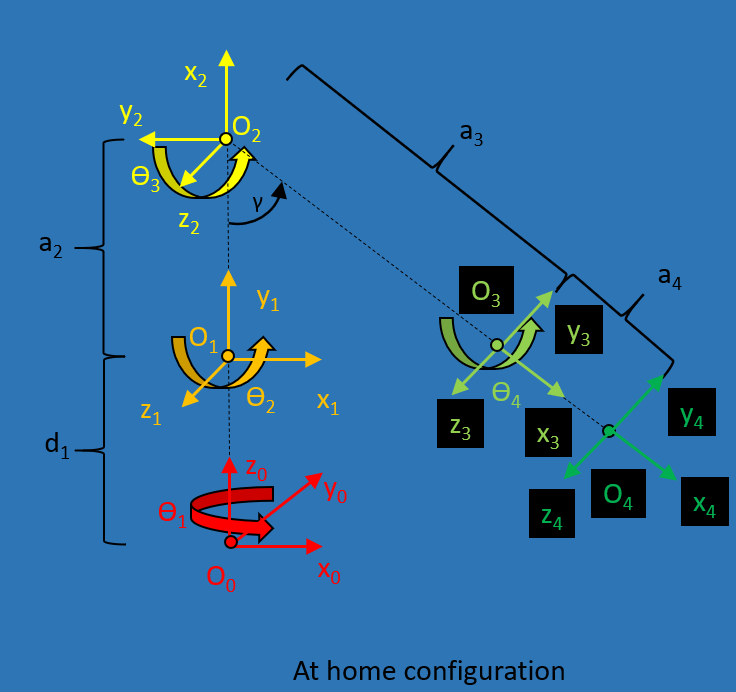

We first explain how the frames were chosen using the DH convention described in pages 86-87 in [1]:

- There are 4 revolute joints and so the z-axes are positioned on the axis of revolutions for these 4 joints ($\left.z_0 ,z_1 ,z_2 ,z_3 \right)\ldotp$

- We establish the base frame ($\left.O_0 \right)$ at ground level and use a right-hand coordinate system and arbitrarily choose direction of $x_0 ,y_0$ for convenience.

- To find the origin of $O_1$ we find the intersection of $z_0$ and $z_1$. To find the origin of $O_2$, we follow the normal between the parallel axes $z_1$ and $z_2$. To find $O_3$, we similarly follow the normal between the parallel axes $z_2$ and $z_3$. $O_4$ is attached to the end-effector. The orientation of the end-effector is identical to $O_3$ (in home config).  

- To find the x-axis of Frame 1, we choose $x_1$ to be perpendicular to $z_0$ and attached to $O_1$. Similarly, to find the x-axis of Frame 2, we choose $x_2$ to be perpendicular to $z_1$ and attached to $O_2$. $x_3$ is along the common normal between $z_2$ and $z_3$ as per DH convention. 

- We find $y_1$ and $y_2$ to complete the right-hand coordinate frames.

We can then proceed with the following steps to obtain the homogeneous transformation matrix that describes the end-effector position and orientation with respect to the base frame:

- Create the DH parameter table, described below.

- Substitute the values from DH parameter table into Equation 3.10 in [1], described below.

- Construct $T_4^0 =A_1 A_2 A_3 A_4$.

To construct the DH parameter value, we list what each parameter describes:

- $\alpha_i \;$: rotate $x_i$ so that $z_{i-1}$ aligns $z_i$

- $\theta_i \;$: rotate $z_{i-1} \;$so that $x_{i-1}$ aligns $x_i$

- $d_i$: displacement along $z_{i-1}$ from $O_{i-1}$ to $O_i$

- $a_i$: displacement along $x_i$ from $O_{i-1}$ to $O_i$

First we look at $a_i$. For link 1, there is no displacement from $O_0$ to $O_1$ along $x_0$ so $a_1 =0$. From $O_1$ to $O_2$ along $x_1$, the displacement is  $a_2$. Similarly, from $O_2$ to $O_3$ along $x_2$, the displacement is $a_3$. Lastly, from $O_3$ to $O_4$ along $x_3$, the displacement is $a_4$.

Now we look at $\alpha_i$. For link 1, to align $z_0$ and $z_1$ about $x_1$ requires 90 deg rotation counter-clockwise (positive rotation). $z_1 ,z_2 ,z_3$ are all parallel, so $\alpha_2 =\alpha_3 =\alpha_4 =0$.

Now we look at $d_i$. For link 1, the displacement from $O_0$ to $O_1$ along $z_0$ is $d_1$. There is no displacement from $O_1$ to $O_2$ along $z_1$ or from $O_2$ to $O_3$ along $z_2$ or from $O_3$ to $O_4$ along $z_3 \;$so $d_2 =d_3 =d_4 =0$.

Lastly, since we aligned the rotation axes of all 3 revolute joints with $z_i$ for i=1,2,3 this corresponds to $\theta_1 ,\theta_2 ,\theta_3$. However, there is a positive rotation of  $\frac{\pi }{2}$  to align $x_1$ and $x_2$ and a negative rotation of  $\frac{\pi }{2}+\gamma \;$ to align $x_2$ and $x_3$. The full DH parameter list is summarized in the table below:

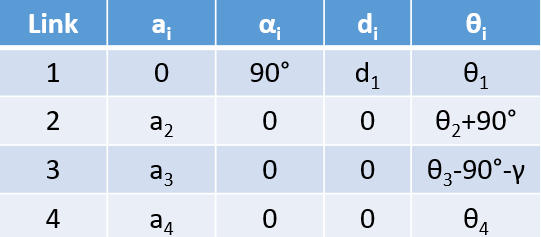

We use the values from DH parameter table above in the general form of the homogeneous transformation matrix $A_i$, given in Eq. 3.10 in [1]:


$$A_i =\left\lbrack \begin{array}{cccc}
c\theta_i  & -s\theta_i c\alpha_i  & s\theta_i s\alpha_i  & a_i c\theta_i \\
s\theta_i \; & c\theta_i c\alpha_i  & -c\theta_i s\alpha_i  & a_i s\theta_i \\
0 & s\alpha_i \; & c\alpha_i \; & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Substituting the values for each link leads to:


$$A_1 =\left\lbrack \begin{array}{cccc}
c\theta_1  & 0 & s\theta_1  & 0\\
s\theta_1 \; & 0 & -c\theta_1  & 0\\
0 & 1 & 0\; & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_2 =\left\lbrack \begin{array}{cccc}
c\left(\theta_2 +\frac{\pi }{2}\right) & -s\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 c\left(\theta_2 +\frac{\pi }{2}\right)\\
s\left(\theta_2 +\frac{\pi }{2}\right)\; & c\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 s\left(\theta_2 +\frac{\pi }{2}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 


$$A_3 =\left\lbrack \begin{array}{cccc}
c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & -s\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 c\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\; & c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_4 =\left\lbrack \begin{array}{cccc}
c\theta_4  & -s\theta_4  & 0 & a_4 c\theta_4 \\
s\theta_4  & c\theta_4  & 0 & a_4 s\theta_4 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


We can then construct the homogeneous transformation matrix that describes the position and orientation of the end-effector frame to the base frame by composing the transformation matrices between each frame as follows:

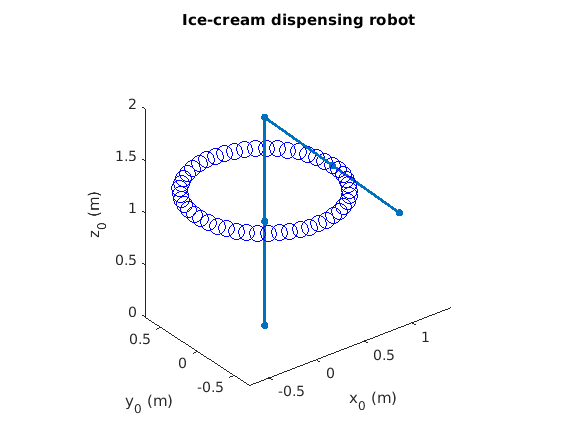

clear all; close
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
intervals = 50;
theta1_vec = linspace(0,2*pi,intervals);
theta2_vec = linspace(0,0,intervals); 
theta3_vec = linspace(0,0,intervals);
theta4_vec = linspace(0,0,intervals);

for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); theta2=theta2_vec(i); theta3=theta3_vec(i); theta4=theta4_vec(i);
    theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,intervals);
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot')

## References

[1] Robot Modeling and Control. Spong, M. W, Hutchnson, S., Vidyasagar, M., Second Edition 2020 Wiley.

## Appendix

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
% Author: Nithin Kumar
% Date: 3/18/2021
% This function calculates the homogeneous transformation matrix H using DH
% convention input parameters and outputs the final H^0_n, the position of all frames
% (P_vec), and all the H matrices.
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));
    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

function plot_link(P_vec,current,end_condition)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    h1=plot3(A,B,C,'.-','MarkerSize',12,'LineWidth',2);
    hold on
    h2=plot3(P_vec(1,3),P_vec(2,3),P_vec(3,3),'bo','MarkerSize',12);
    axis equal
    pause(0.05)
    if current~=end_condition && current~=1
        delete(h1)
    end
    
end